# Varying population size with IT constructed with options B and C; gap timing

## load and preprocess data

fds = fileDatastore('N-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
npop = length(Filenames);

pop = zeros(1,npop);
C = cell(1,npop);
for i = 1:npop
    load(Filenames{i});
    C{1,i} = c;
    nums = regexp(Filenames{i},'\d*','Match');
    nums = str2double(nums);
    pop(i) = nums(end);
end

[pop, order] = sort(pop);
[r,c] = size(pop);
index = bsxfun( @plus, order, (0:r-1)'*c );
C = C';
C = C(index')';

## analyze data

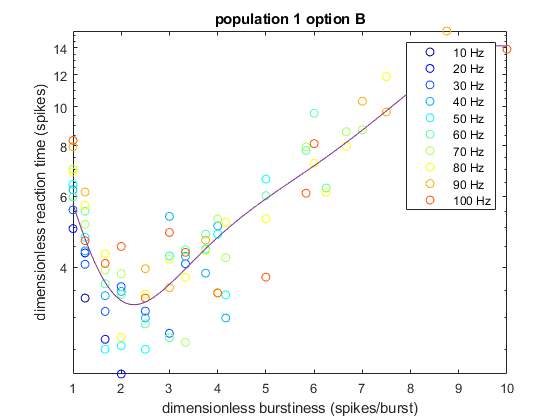

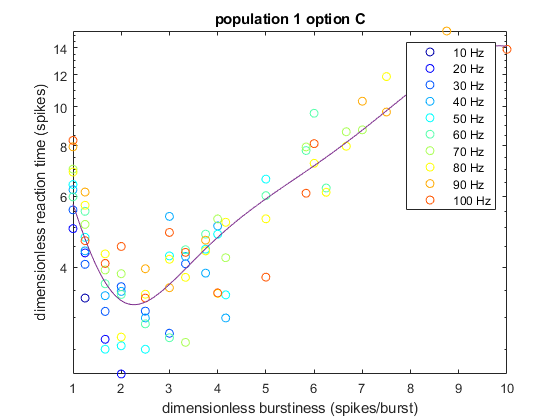

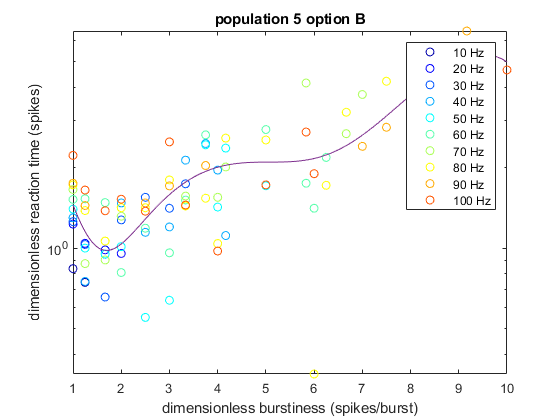

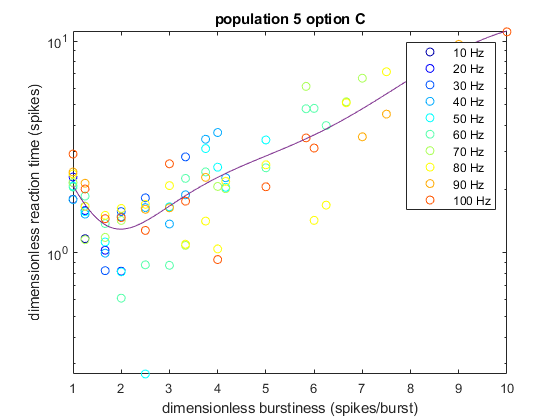

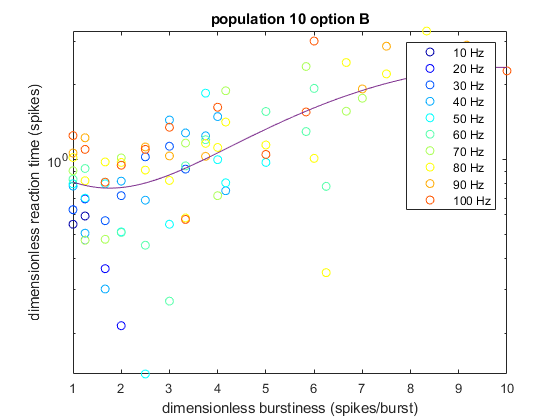

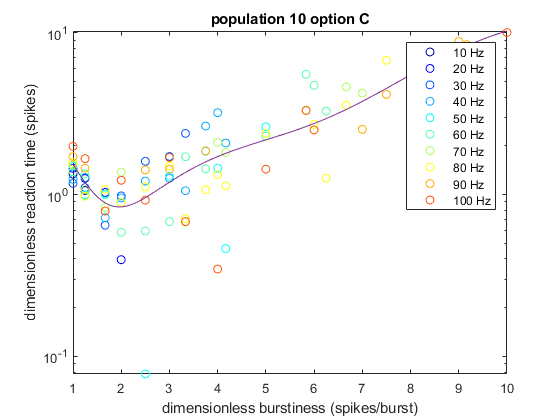

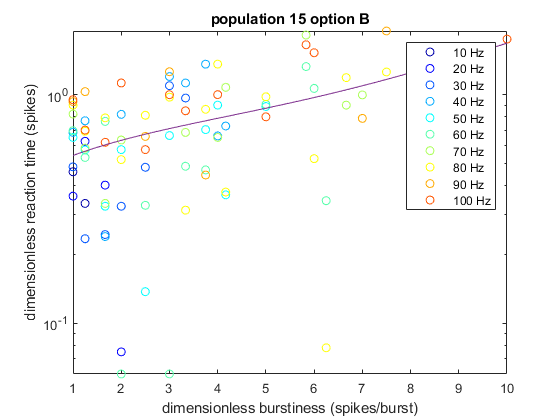

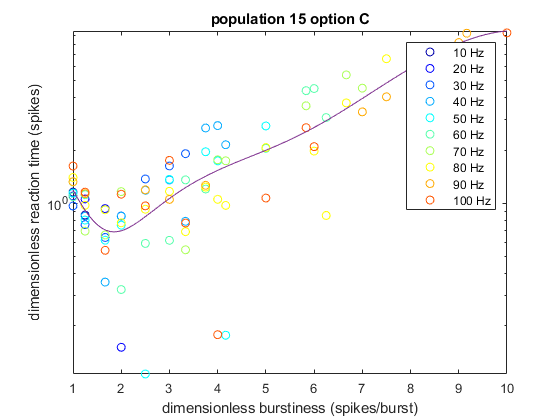

% generate a random color for each firing rate
mycolors = jet(10);
fr_vals = 10:10:100;

for k = 1:npop
    figure;
    c = C{k};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT1 = zeros(nparams, ntrials);
    RT2 = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT1(ii,jj) = c{ii,jj}.performance1(1,3);
            RT2(ii,jj) = c{ii,jj}.performance2(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT1 = median(RT1,2);
    RT2 = median(RT2,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT1;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    hold on
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    if k == 1 || k==2
        p = polyfit(fit_x,fit_y,5);
    else
        p = polyfit(fit_x,fit_y,3);
    end
    yy = polyval(p,xx);
    semilogy(xx,yy)
    hold off
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
    title(['population ', num2str(pop(k)),' option B'])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
    
    figure;
    rt = RT2;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    hold on
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    p = polyfit(fit_x,fit_y,5);
    yy = polyval(p,xx);
    semilogy(xx,yy)
    hold off
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
    title(['population ', num2str(pop(k)),' option C'])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
end

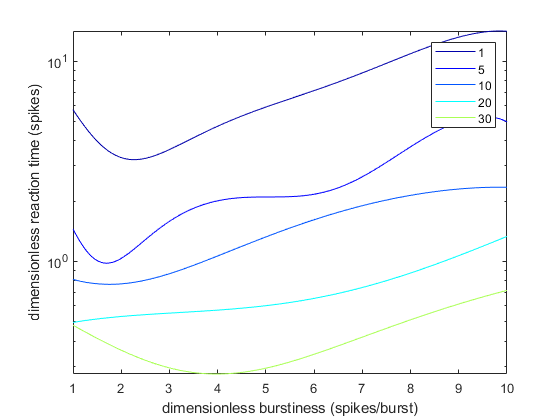

% choose 5 population sizes (for the sake of readability) and plot the
% corresponding polynomial fits
mycolors2 = jet(npop);
mypop = [1 2 3 5 7];
for k = 1:length(mypop)
    c = C{mypop(k)};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT1 = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT1(ii,jj) = c{ii,jj}.performance1(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT1 = median(RT1,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT1;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    if mypop(k) == 1 || mypop(k)==2
        p = polyfit(fit_x,fit_y,5);
    else
        p = polyfit(fit_x,fit_y,3);
    end
    yy = polyval(p,xx);
    semilogy(xx,yy,'color',mycolors(mypop(k),:))
    hold on
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
end
hold off
legend('1','5','10','20','30')

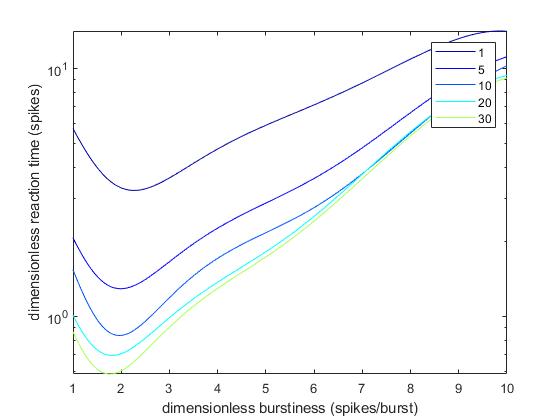




for k = 1:length(mypop)
    c = C{mypop(k)};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT2 = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT2(ii,jj) = c{ii,jj}.performance2(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT2 = median(RT2,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT2;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    p = polyfit(fit_x,fit_y,5);
    yy = polyval(p,xx);
    semilogy(xx,yy,'color',mycolors(mypop(k),:))
    hold on
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
end
hold off
legend('1','5','10','20','30')

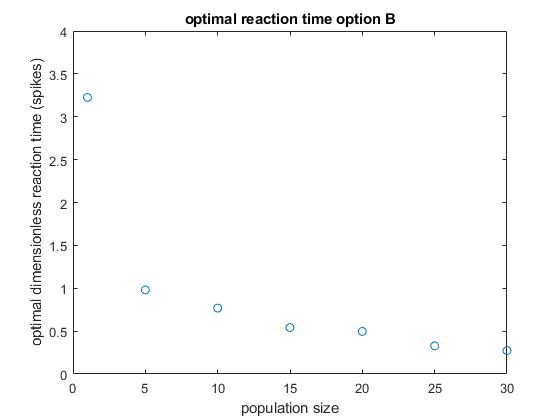

close all hidden;
optimal_burst_predictionB = zeros(npop,1);
optimal_rt_predictionB = zeros(npop,1);

for k = 1:npop
    c = C{k};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT1 = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT1(ii,jj) = c{ii,jj}.performance1(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT1 = median(RT1,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT1;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    if k == 1 || k==2
        p = polyfit(fit_x,fit_y,5);
    else
        p = polyfit(fit_x,fit_y,3);
    end
    yy = polyval(p,xx);
    [~,min_ind] = min(yy);    
    optimal_burst_predictionB(k) = xx(min_ind);
    optimal_rt_predictionB(k) = yy(min_ind);
end

plot(pop,optimal_rt_predictionB,'o')
ylim([0 4])
ylabel('optimal dimensionless reaction time (spikes)')
xlabel('population size')
title('optimal reaction time option B')

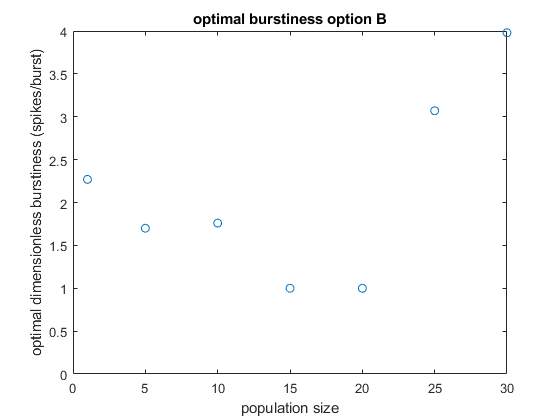


plot(pop,optimal_burst_predictionB,'o')
ylim([0 4])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('population size')
title('optimal burstiness option B')

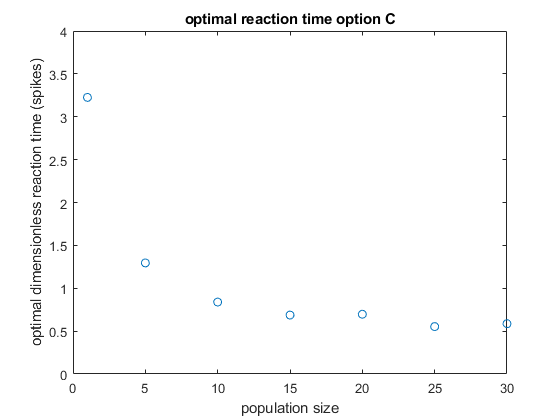

close all hidden;
optimal_burst_predictionC = zeros(npop,1);
optimal_rt_predictionC = zeros(npop,1);

for k = 1:npop
    c = C{k};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT2 = zeros(nparams, ntrials);
    for ii = 1:nparams
        for jj = 1:ntrials
            RT2(ii,jj) = c{ii,jj}.performance2(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);  
    lambda2 = params(:,2);
    k1 = params(:,3);
    k2 = params(:,4);
    fr = params(:,5);
    fr = round(fr,-1);
    burstiness = k1./lambda1;
    fr1 = lambda1./k1;
    fr2 = lambda2./k2;
    fr_exact = lambda1.*lambda2./(k1.*k2);
    RT2 = median(RT2,2);
    
    lambda_s = fr_exact;
    lambda_s_round = fr;
    rt = RT2;
    y = rt.*lambda_s./1000;
    x = fr2;

    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(lambda_s_round == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    fit_error = zeros(length(fit_x),1);
    for j = 1:length(fit_x)
        fit_y(j) = median(all_y(all_x == fit_x(j)));
        fit_error(j) = iqr(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    xx = 1:0.01:max(fit_x);
    p = polyfit(fit_x,fit_y,5);
    yy = polyval(p,xx);
    [~,min_ind] = min(yy);    
    optimal_burst_predictionC(k) = xx(min_ind);
    optimal_rt_predictionC(k) = yy(min_ind);
end

plot(pop,optimal_rt_predictionC,'o')
ylim([0 4])
ylabel('optimal dimensionless reaction time (spikes)')
xlabel('population size')
title('optimal reaction time option C')

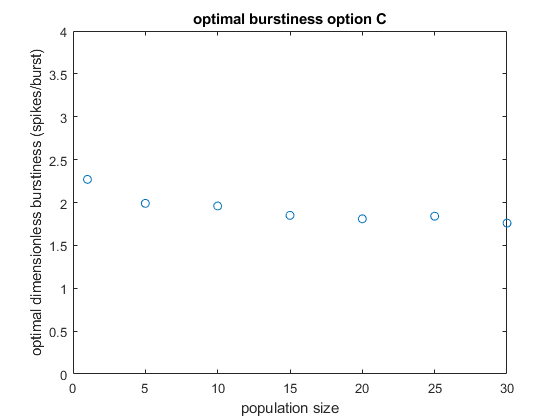


plot(pop,optimal_burst_predictionC,'o')
ylim([0 4])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('population size')
title('optimal burstiness option C')

## example plots shown in paper

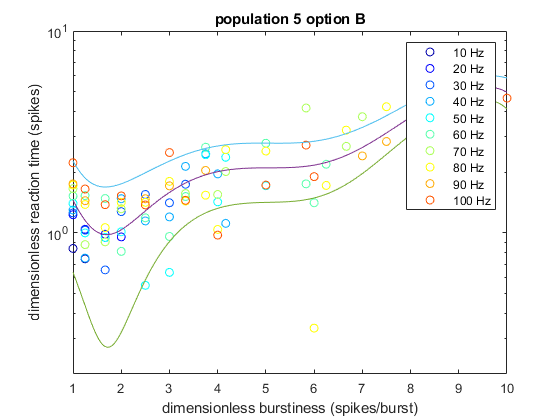

close all hidden;
c = C{2};
nparams = size(c,1); % number of sets of firing rate parameters
ntrials = size(c,2)-5; % number of trials

RT1 = zeros(nparams, ntrials);
RT2 = zeros(nparams, ntrials);
for ii = 1:nparams
    for jj = 1:ntrials
        RT1(ii,jj) = c{ii,jj}.performance1(1,3);
        RT2(ii,jj) = c{ii,jj}.performance2(1,3);
    end
end

params = c(:,ntrials+1:ntrials+5);
params = cell2mat(params);
lambda1 = params(:,1);  
lambda2 = params(:,2);
k1 = params(:,3);
k2 = params(:,4);
fr_exact = params(:,5);
fr = round(fr_exact,-1);
burstiness = k1./lambda1;
fr1 = lambda1./k1;
fr2 = lambda2./k2;
RT1 = median(RT1,2);
RT2 = median(RT2,2);
    
lambda_s = fr_exact;
rt = RT1;
y = rt.*lambda_s./1000;
x = fr2;

all_x = [];
all_y = [];
for i = 1:length(fr_vals)
    rows2 = find(fr == fr_vals(i));
    this_x = x(rows2);
    this_y = y(rows2);
    x_vals = unique(this_x);
    y_vals = zeros(length(x_vals),1);
    for j = 1:length(x_vals)
        y_vals(j) = median(this_y(this_x == x_vals(j)));
    end
    semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
    all_x = [all_x; x_vals];
    all_y = [all_y; y_vals];
    hold on
end
fit_x = unique(all_x);
fit_y = zeros(length(fit_x),1);
fit_error = zeros(length(fit_x),1);
for j = 1:length(fit_x)
    fit_y(j) = median(all_y(all_x == fit_x(j)));
    fit_error(j) = iqr(all_y(all_x == fit_x(j)));
end
xq = 1:0.01:10;
yq = interp1(fit_x,fit_y,xq,'spline');
xx = 1:0.01:10;
[p, S, mu] = polyfit(fit_x,fit_y,5);
[yy, delta] = polyval(p,xx,S, mu);
semilogy(xx,yy)
hold on
semilogy(xx,yy-delta)
hold on
semilogy(xx,yy+delta)
hold off
ylabel('dimensionless reaction time (spikes)')
xlabel('dimensionless burstiness (spikes/burst)')
title('population 5 option B')
ylim([0.2 10])
legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')

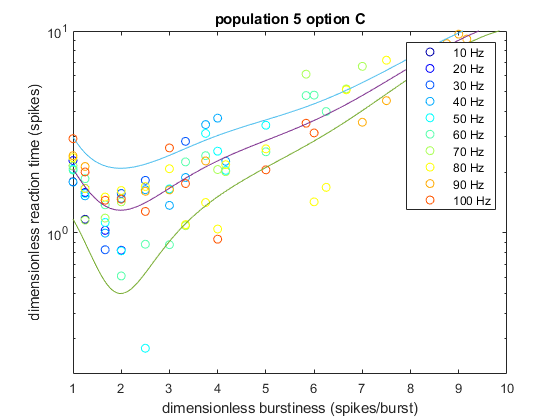

rt = RT2;
y = rt.*lambda_s./1000;
x = fr2;

all_x = [];
all_y = [];
for i = 1:length(fr_vals)
    rows2 = find(fr == fr_vals(i));
    this_x = x(rows2);
    this_y = y(rows2);
    x_vals = unique(this_x);
    y_vals = zeros(length(x_vals),1);
    for j = 1:length(x_vals)
        y_vals(j) = median(this_y(this_x == x_vals(j)));
    end
    semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
    all_x = [all_x; x_vals];
    all_y = [all_y; y_vals];
    hold on
end
fit_x = unique(all_x);
fit_y = zeros(length(fit_x),1);
fit_error = zeros(length(fit_x),1);
for j = 1:length(fit_x)
    fit_y(j) = median(all_y(all_x == fit_x(j)));
    fit_error(j) = iqr(all_y(all_x == fit_x(j)));
end
xq = 1:0.01:10;
yq = interp1(fit_x,fit_y,xq,'spline');
xx = 1:0.01:10;
[p, S, mu] = polyfit(fit_x,fit_y,5);
[yy, delta] = polyval(p,xx,S, mu);
semilogy(xx,yy)
hold on
semilogy(xx,yy-delta)
hold on
semilogy(xx,yy+delta)
hold off
ylabel('dimensionless reaction time (spikes)')
xlabel('dimensionless burstiness (spikes/burst)')
title('population 5 option C')
ylim([0.2 10])
legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')